# Script # 2: Diversity and MRC

Written by Henk Wymeersch, (c) 2019, for the course Wireless Communications (SSY135), Chalmers University of Technology

## Set up the system

We will consider a diversity system with $M\ge 1$ branches. We first generate the channels and QPSK data. 

clear all
M = 40;                  % number of branches
N=1000;                 % number of channel realizations
Es = 4;                 % signal energy per channel
N0 = 0.2; 
gamma = Es/N0;          %average SNR per channel
h =sqrt(Es/(2*M))*(randn(M,N)+1j*randn(M,N));            % channel with constant energy
%h =sqrt(Es/(2))*(randn(M,N)+1j*randn(M,N));            % channel with increasing energy with M
a = (2*round(rand(1,N))-1) + 1j*(2*round(rand(1,N))-1);
a = a / sqrt(2);        % normalize to unit energy

Now we generate the observation with AWGN $\sim \mathcal{CN}(0,N_0)$:

y = h.*repmat(a,M,1) + sqrt(N0/2)*(randn(M,N)+1j*randn(M,N));   

## Maximum ratio combining

As a first step we will look at the output after MRC. For the n-th transmission ($n \in \{1,\ldots,N\}$) the observation is $\mathbf{y}_n = \mathbf{h}_n a_n + \mathbf{w}_n$, which after MRC becomes $z_n = \mathbf{h}^{H}_n \mathbf{y}_n$. The channel after MRC should look more and more like an AWGN channel. We look at a scatter plot of the MRC outputs and then compute the SNR distribution. 

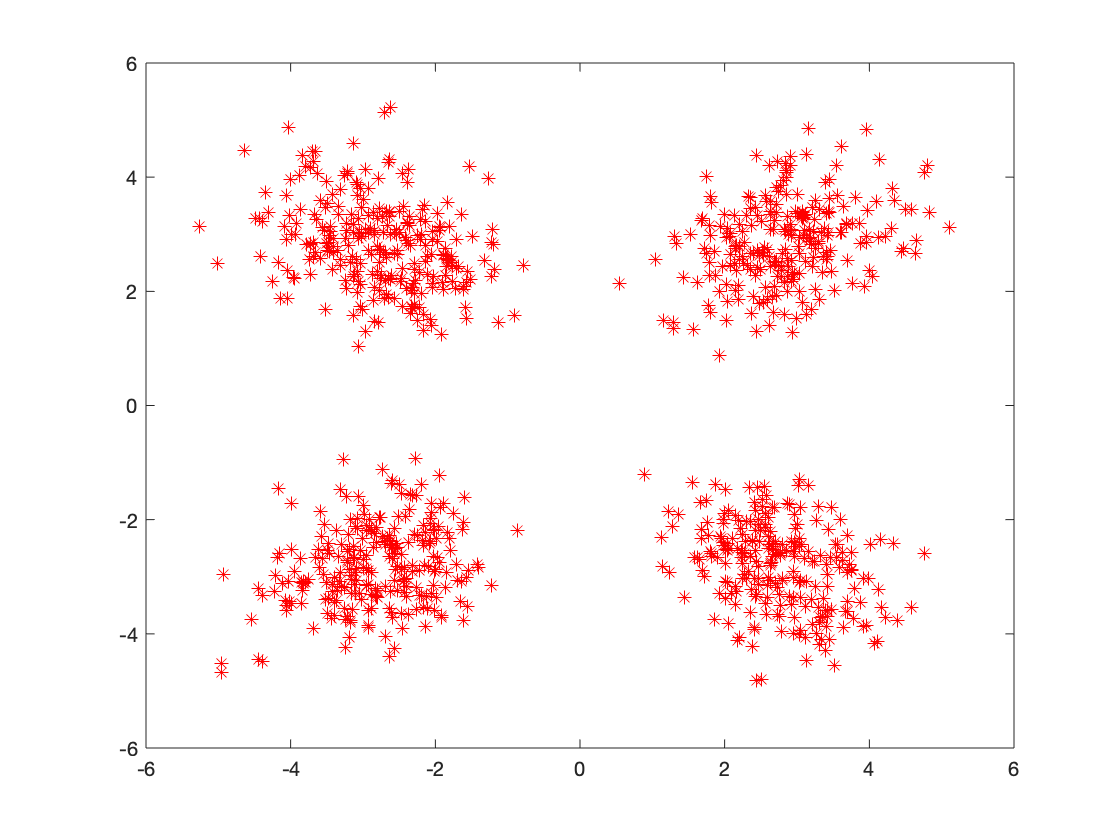

z = diag(h'*y);
plot(real(z),imag(z),'r*');

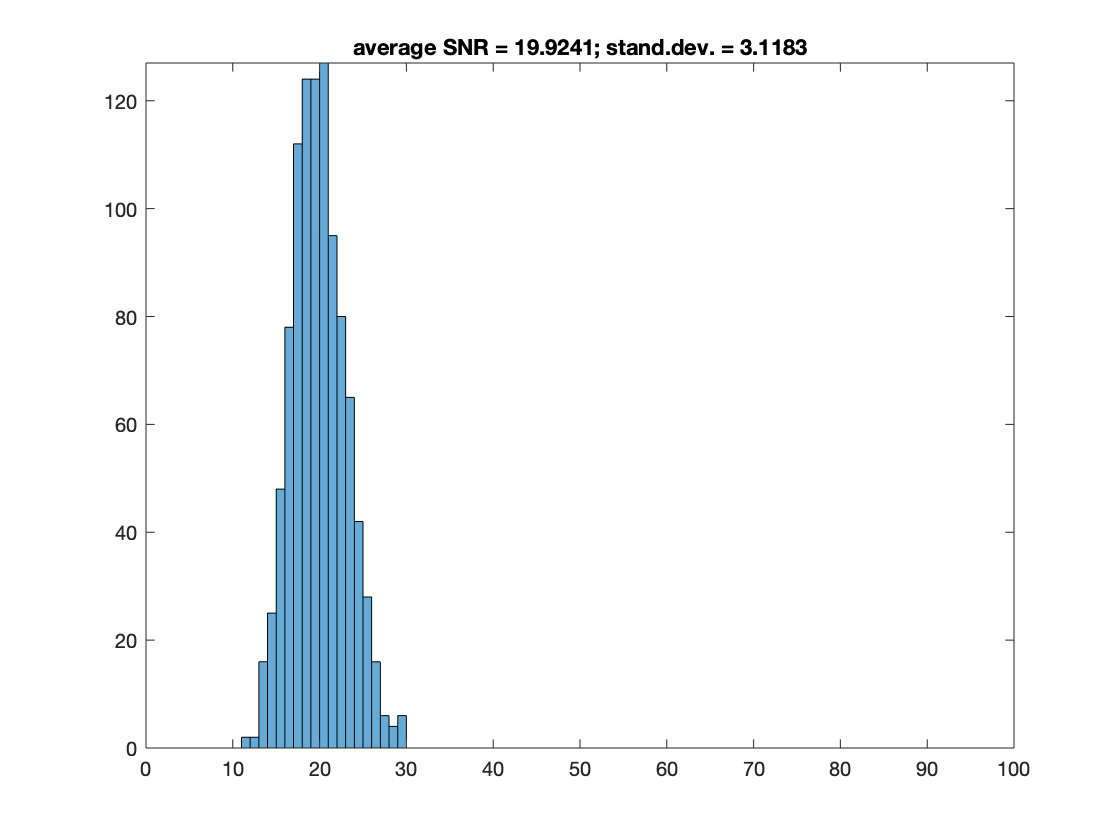

H=diag(h'*h);
SNR_MRC=abs(H).^2./(abs(H)*N0);
hii=histogram(SNR_MRC);
axis([0 5*gamma 0 max(hii.Values)])
title(['average SNR = ' num2str(mean(SNR_MRC)) '; stand.dev. = ' num2str(std(SNR_MRC))]);

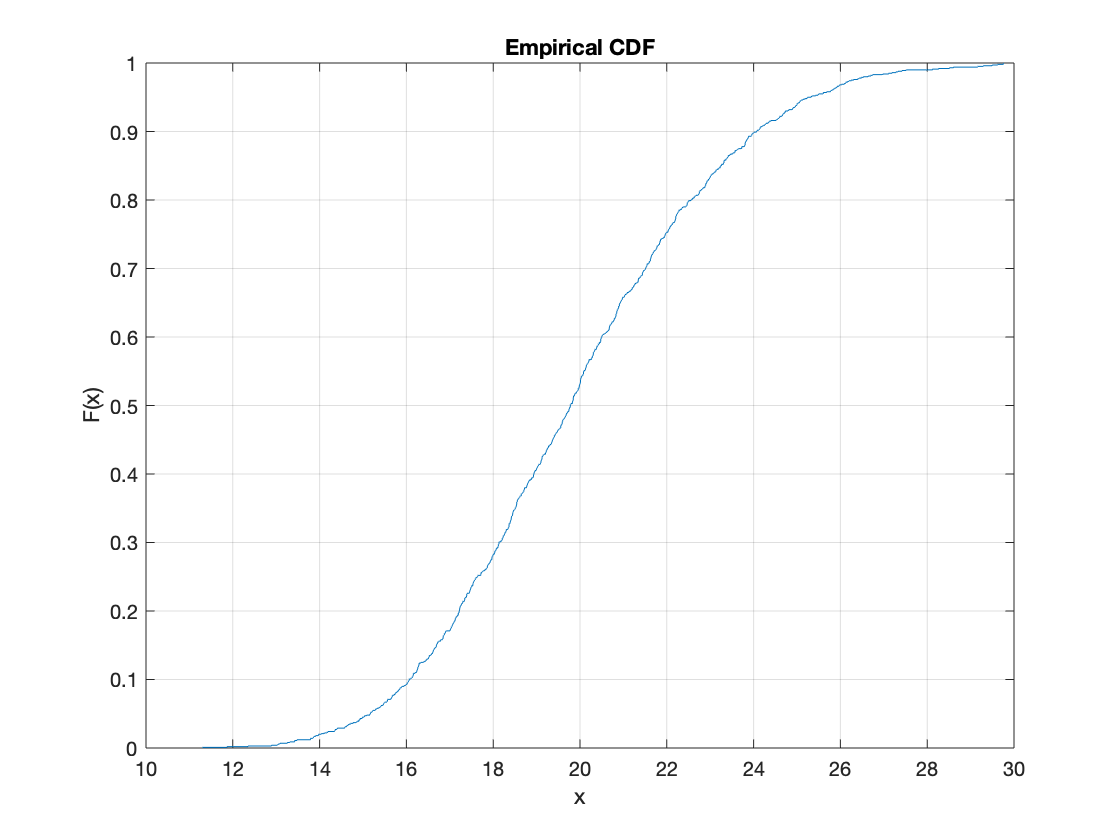


cdfplot(SNR_MRC)

% note that mean(SNR_MRC) = Es/N0


## Symbol error rate computation

To compute the SER, we will compare the phase of $a_i$ with the phase of $z_i$. The phase difference should be less than $\pi/4$ in magnitude to have no error for QPSK. 

phase_error=angle(z)-angle(a.');
phase_error=mod(phase_error,2*pi);
phase_error(phase_error>pi)=phase_error(phase_error>pi)-2*pi;
numberOfErrors=sum(abs(phase_error)>pi/4);
SER=numberOfErrors/N

SER = 0